# Opgave a og b

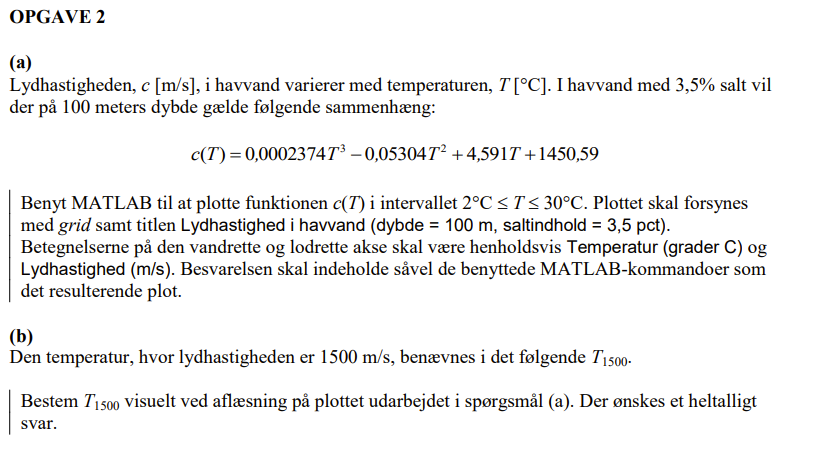

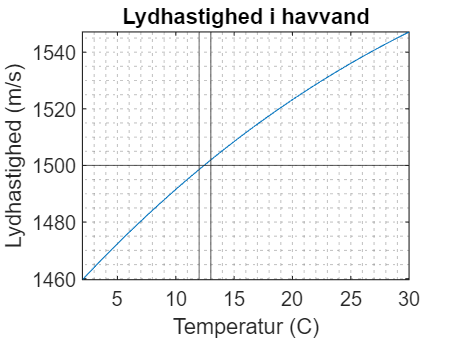

cT = @(T) 0.0002374*T.^3 - 0.05304*T.^2 + 4.593*T + 1450.69;


fplot(cT, [2, 30]), grid("minor"), title("Lydhastighed i havvand")
xlabel("Temperatur (C)"), ylabel("Lydhastighed (m/s)")

yline(1500), xline(12), xline(13)


fprintf("Svar til b) 12 grader")

Svar til b) 12 grader

# Opgave C

f = @(T) 0.0002374*T^3 - 0.05304*T^2 + 4.591*T + 1450.59 - 1500;
Tl = 10; % Nedre intervalendepunkt (grader C)
Tu = 15; % Øvre intervalendepunkt (grader C)
es = 0.01; % Ønsket nøjagtighed af rod (%)
maksit = 20; % Maksimal antal iterationer
it = 0; % Startværdi for iterationstælleren it
while 1
    Tr = (Tl + Tu)/2;
    ea = abs(Tr-Tl)/Tr*100;
    it = it + 1;

    if f(Tl)*f(Tr) > 0
        Tl = Tr;

    elseif f(Tl)*f(Tr) < 0
        Tu = Tr;

    else
        ea = 0;

    end

    if ea <= es || it >= maksit
        break
    end
end

fprintf("Opgave c")

Opgave c

T1500 = Tr

T1500 = 12.4548

ea

ea = 0.0098

it

it = 12

ea er relative fejl i estimeringen, som ønskes lavere end es. it er antallet af loops (iterationer) som scriptet har kørt for at opnå den ønskede præcision. While loopet kører så længe det er "true" (1), og stopper efter n iterationer når betingelserne er nået.

# Opgave e og f

f = @(T) 0.0002374*T^3 - 0.05304*T^2 + 4.591*T + 1450.59 - 1500;

fprintf("Opgave e")

Opgave e

fzero(f, [2, 32])

ans = 12.4545

roots(

fprintf("Opgave f")

Opgave f

%ff = 0.0002374*T^3 - 0.05304*T^2 + 4.591*T + 1450.59 - 1500;
r = roots([0.0002374, -0.05304, 4.591, -49.41])

r = 1.0e+02 *

   1.0548 + 0.7473i
   1.0548 - 0.7473i
   0.1245 + 0.0000i


Her ses det at fzero giver et mere præcist svar, end bisektionsmetoden, da funktionen returnerer den eksakte værdi, hvorimod bisektion giver et svar givet en ønsket præcision.

roots funktionen kræver et f^n + f^n-1..  polynomie, der giver n løsninger, hvor vi her har et 3. grads polynomie, som funktionen løser for alle mulige løsninger - hvor det ses det rigtigte svar er den tredje løsning.